# Example: Plotting

In this example, we will plot 4 different variations of the same function: 


$$f_1(x) = x^2 , \quad f_2(x) = 4x^2 , \quad f_3(x) = x^2 - 4, \quad f_4(x) = (x-2)^2$$


Let's do this using matrices and by leveraging all the matrix manipulation operations we just learned. We ultimately want to have a matrix where each row represents the value of each of these functions. That is, we want a matrix that looks like


$$\left[ \matrix{
f_1(x) \cr f_2(x) \cr f_3(x) \cr f_4(x)
}\right] =
\left[ \matrix{
f_1(x_1) & f_1(x_2) & \dots & f_1(x_n) \cr 
f_2(x_1) & f_2(x_2) & \dots & f_2(x_n) \cr 
f_3(x_1) & f_3(x_2) & \dots & f_3(x_n) \cr 
f_4(x_1) & f_4(x_2) & \dots & f_4(x_n)
}\right] $$


**Make the **`x`** vector**

x = -5:0.1:5 % make a vector for x ranging from -5 to 5, spaced by 0.1

x =   -5.0000e+00  -4.9000e+00  -4.8000e+00  -4.7000e+00  -4.6000e+00  -4.5000e+00  -4.4000e+00  -4.3000e+00  -4.2000e+00  -4.1000e+00  -4.0000e+00  -3.9000e+00  -3.8000e+00  -3.7000e+00  -3.6000e+00  -3.5000e+00  -3.4000e+00  -3.3000e+00  -3.2000e+00  -3.1000e+00  -3.0000e+00  -2.9000e+00  -2.8000e+00  -2.7000e+00  -2.6000e+00  -2.5000e+00  -2.4000e+00  -2.3000e+00  -2.2000e+00  -2.1000e+00  -2.0000e+00  -1.9000e+00  -1.8000e+00  -1.7000e+00  -1.6000e+00  -1.5000e+00  -1.4000e+00  -1.3000e+00  -1.2000e+00  -1.1000e+00  -1.0000e+00  -9.0000e-01  -8.0000e-01  -7.0000e-01  -6.0000e-01  -5.0000e-01  -4.0000e-01  -3.0000e-01  -2.0000e-01  -1.0000e-01


**Make a matrix where each row represents the x vector**

y = ones(4,1).*x % multiply a column vector of ones by the x vector, element-by-element

y =   -5.0000e+00  -4.9000e+00  -4.8000e+00  -4.7000e+00  -4.6000e+00  -4.5000e+00  -4.4000e+00  -4.3000e+00  -4.2000e+00  -4.1000e+00  -4.0000e+00  -3.9000e+00  -3.8000e+00  -3.7000e+00  -3.6000e+00  -3.5000e+00  -3.4000e+00  -3.3000e+00  -3.2000e+00  -3.1000e+00  -3.0000e+00  -2.9000e+00  -2.8000e+00  -2.7000e+00  -2.6000e+00  -2.5000e+00  -2.4000e+00  -2.3000e+00  -2.2000e+00  -2.1000e+00  -2.0000e+00  -1.9000e+00  -1.8000e+00  -1.7000e+00  -1.6000e+00  -1.5000e+00  -1.4000e+00  -1.3000e+00  -1.2000e+00  -1.1000e+00  -1.0000e+00  -9.0000e-01  -8.0000e-01  -7.0000e-01  -6.0000e-01  -5.0000e-01  -4.0000e-01  -3.0000e-01  -2.0000e-01  -1.0000e-01
  -5.0000e+00  -4.9000e+00  -4.8000e+00  -4.7000e+00  -4.6000e+00  -4.5000e+00  -4.4000e+00  -4.3000e+00  -4.2000e+00  -4.1000e+00  -4.0000e+00  -3.9000e+00  -3.8000e+00  -3.7000e+00  -3.6000e+00  -3.5000e+00  -3.4000e+00  -3.3000e+00  -3.2000e+00  -3.1000e+00  -3.0000e+00  -2.9000e+00  -2.8000e+00  -2.7000e+00  -2.6000e+00  -2.5000e+00  -2.40

**Perform any necessary manipulations to the x values before squaring each element of **`y` 

b = [0 0 0 -2]' % create a column vector that will allow us to subtract 2 from last row of y

b =      0
     0
     0
    -2


y = y + b % add a vector to y

y =   -5.0000e+00  -4.9000e+00  -4.8000e+00  -4.7000e+00  -4.6000e+00  -4.5000e+00  -4.4000e+00  -4.3000e+00  -4.2000e+00  -4.1000e+00  -4.0000e+00  -3.9000e+00  -3.8000e+00  -3.7000e+00  -3.6000e+00  -3.5000e+00  -3.4000e+00  -3.3000e+00  -3.2000e+00  -3.1000e+00  -3.0000e+00  -2.9000e+00  -2.8000e+00  -2.7000e+00  -2.6000e+00  -2.5000e+00  -2.4000e+00  -2.3000e+00  -2.2000e+00  -2.1000e+00  -2.0000e+00  -1.9000e+00  -1.8000e+00  -1.7000e+00  -1.6000e+00  -1.5000e+00  -1.4000e+00  -1.3000e+00  -1.2000e+00  -1.1000e+00  -1.0000e+00  -9.0000e-01  -8.0000e-01  -7.0000e-01  -6.0000e-01  -5.0000e-01  -4.0000e-01  -3.0000e-01  -2.0000e-01  -1.0000e-01
  -5.0000e+00  -4.9000e+00  -4.8000e+00  -4.7000e+00  -4.6000e+00  -4.5000e+00  -4.4000e+00  -4.3000e+00  -4.2000e+00  -4.1000e+00  -4.0000e+00  -3.9000e+00  -3.8000e+00  -3.7000e+00  -3.6000e+00  -3.5000e+00  -3.4000e+00  -3.3000e+00  -3.2000e+00  -3.1000e+00  -3.0000e+00  -2.9000e+00  -2.8000e+00  -2.7000e+00  -2.6000e+00  -2.5000e+00  -2.40

**Square each element of **`y`

y = y.^2 % square y element-by-element

y =    2.5000e+01   2.4010e+01   2.3040e+01   2.2090e+01   2.1160e+01   2.0250e+01   1.9360e+01   1.8490e+01   1.7640e+01   1.6810e+01   1.6000e+01   1.5210e+01   1.4440e+01   1.3690e+01   1.2960e+01   1.2250e+01   1.1560e+01   1.0890e+01   1.0240e+01   9.6100e+00   9.0000e+00   8.4100e+00   7.8400e+00   7.2900e+00   6.7600e+00   6.2500e+00   5.7600e+00   5.2900e+00   4.8400e+00   4.4100e+00   4.0000e+00   3.6100e+00   3.2400e+00   2.8900e+00   2.5600e+00   2.2500e+00   1.9600e+00   1.6900e+00   1.4400e+00   1.2100e+00   1.0000e+00   8.1000e-01   6.4000e-01   4.9000e-01   3.6000e-01   2.5000e-01   1.6000e-01   9.0000e-02   4.0000e-02   1.0000e-02
   2.5000e+01   2.4010e+01   2.3040e+01   2.2090e+01   2.1160e+01   2.0250e+01   1.9360e+01   1.8490e+01   1.7640e+01   1.6810e+01   1.6000e+01   1.5210e+01   1.4440e+01   1.3690e+01   1.2960e+01   1.2250e+01   1.1560e+01   1.0890e+01   1.0240e+01   9.6100e+00   9.0000e+00   8.4100e+00   7.8400e+00   7.2900e+00   6.7600e+00   6.2500e+00   5.76

**Scale x^2 values by any multiplicative factors**

b = [1 4 1 1]' % scale factor column vector for y

b =      1
     4
     1
     1


y = y.*b % multiply b and y element-by-element

y =    2.5000e+01   2.4010e+01   2.3040e+01   2.2090e+01   2.1160e+01   2.0250e+01   1.9360e+01   1.8490e+01   1.7640e+01   1.6810e+01   1.6000e+01   1.5210e+01   1.4440e+01   1.3690e+01   1.2960e+01   1.2250e+01   1.1560e+01   1.0890e+01   1.0240e+01   9.6100e+00   9.0000e+00   8.4100e+00   7.8400e+00   7.2900e+00   6.7600e+00   6.2500e+00   5.7600e+00   5.2900e+00   4.8400e+00   4.4100e+00   4.0000e+00   3.6100e+00   3.2400e+00   2.8900e+00   2.5600e+00   2.2500e+00   1.9600e+00   1.6900e+00   1.4400e+00   1.2100e+00   1.0000e+00   8.1000e-01   6.4000e-01   4.9000e-01   3.6000e-01   2.5000e-01   1.6000e-01   9.0000e-02   4.0000e-02   1.0000e-02
   1.0000e+02   9.6040e+01   9.2160e+01   8.8360e+01   8.4640e+01   8.1000e+01   7.7440e+01   7.3960e+01   7.0560e+01   6.7240e+01   6.4000e+01   6.0840e+01   5.7760e+01   5.4760e+01   5.1840e+01   4.9000e+01   4.6240e+01   4.3560e+01   4.0960e+01   3.8440e+01   3.6000e+01   3.3640e+01   3.1360e+01   2.9160e+01   2.7040e+01   2.5000e+01   2.30

**Shift x^2 values**

c = [0 0 -4 0]' % shift values for each row of y

c =      0
     0
    -4
     0


**Finally, adding constant**

y = y+c % add c to y element-by-element

y =    2.5000e+01   2.4010e+01   2.3040e+01   2.2090e+01   2.1160e+01   2.0250e+01   1.9360e+01   1.8490e+01   1.7640e+01   1.6810e+01   1.6000e+01   1.5210e+01   1.4440e+01   1.3690e+01   1.2960e+01   1.2250e+01   1.1560e+01   1.0890e+01   1.0240e+01   9.6100e+00   9.0000e+00   8.4100e+00   7.8400e+00   7.2900e+00   6.7600e+00   6.2500e+00   5.7600e+00   5.2900e+00   4.8400e+00   4.4100e+00   4.0000e+00   3.6100e+00   3.2400e+00   2.8900e+00   2.5600e+00   2.2500e+00   1.9600e+00   1.6900e+00   1.4400e+00   1.2100e+00   1.0000e+00   8.1000e-01   6.4000e-01   4.9000e-01   3.6000e-01   2.5000e-01   1.6000e-01   9.0000e-02   4.0000e-02   1.0000e-02
   1.0000e+02   9.6040e+01   9.2160e+01   8.8360e+01   8.4640e+01   8.1000e+01   7.7440e+01   7.3960e+01   7.0560e+01   6.7240e+01   6.4000e+01   6.0840e+01   5.7760e+01   5.4760e+01   5.1840e+01   4.9000e+01   4.6240e+01   4.3560e+01   4.0960e+01   3.8440e+01   3.6000e+01   3.3640e+01   3.1360e+01   2.9160e+01   2.7040e+01   2.5000e+01   2.30

**Plot all rows of y**

There are a few ways to do this. The easiest way is to let MATLAB's `plot` function reognize that $\textbf{y}$ has multiple rows. It will automatically parse this and create 4 lines, one representing each row. Click [here](https://www.mathworks.com/help/matlab/ref/plot.html) to learn more about MATLAB plotting.

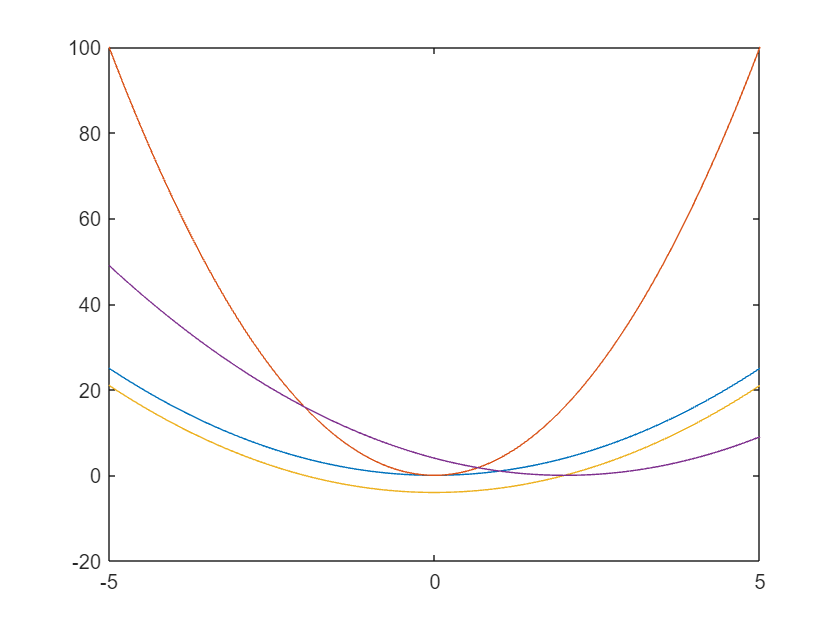

figure(1) % make a figure for single plot command below
plot(x,y)

However, let's do this by leveraging the matrix indexing we learned.

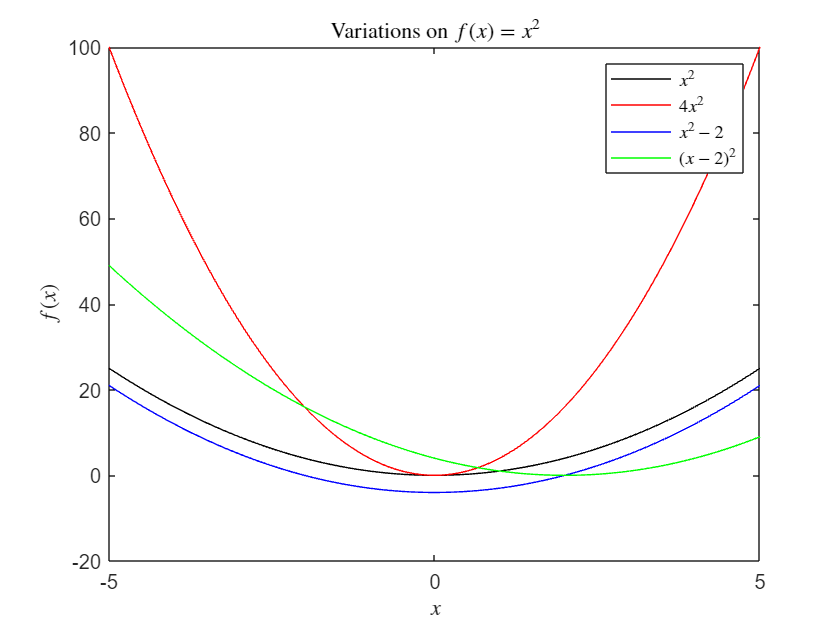

% close all
figure(2) % make a new figure for plot commands below
plot(x,y(1,:),'k') % plot first row, all columns, of y in black
hold on % keep the current line on the open figure
plot(x,y(2,:),'r') % plot the second row, all columns, of y in red
plot(x,y(3,:),'b') % plot the third row, all columns, of y in blue
plot(x,y(4,:),'g') % plot the fourth row, all columns, of y in green
title('Variations on $f(x) = x^2$','Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$f(x)$','Interpreter','latex')
legend('$x^2$','$4x^2$','$x^2 - 2$','$(x-2)^2$','interpreter','latex')